clear
close all
targetImage = im2double(imread("dogdogorange.png"));

imagefiles = dir("data64\cat\*.jpg");
filepath = "data64\cat"

filepath = "data64\cat"


rTileSize = 64;
oTileSize = 8;
tileRatio = oTileSize/rTileSize*4;
nrOfPrimaryColours = 5;

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 109

tileCols = ceil(cols / oTileSize)

tileCols = 88


outputImage = zeros(tileRows*rTileSize*tileRatio, tileCols*rTileSize*tileRatio,3);
%outputImage = zeros(tileRows*rTileSize, tileCols*rTileSize,3);

processbar = waitbar(0, 'Loading Images...');
numberOfImages = 2000%15165

numberOfImages = 2000

for ii=1:numberOfImages
    waitbar(ii/numberOfImages, processbar, "Loading Images...");
    currentfilename = imagefiles(ii).name;
    currentimage = im2double(imread(filepath + "\" +  currentfilename));
    %currentimage = imresize(currentimage, tileRatio);
    images{ii, 1} = currentimage;
    images{ii, 2} = getImportantColours(currentimage, nrOfPrimaryColours);
end
close(processbar)

images{1,2}

ans =     0.8431    0.9373    0.3137    0.3569    0.6431
    0.8471    0.9176    0.2392    0.3020    0.5961
    0.8275    0.8941    0.2118    0.2667    0.5412
    0.6665    0.2087    0.0764    0.0361    0.0095


processbar = waitbar(0, 'Load Colours...');
for c = 1:tileCols 
    waitbar(c/tileCols, processbar, "Load Colours...");
    for r = 1:tileRows       
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);
        wantedTiles{r,c} = currentTile;
        targetPrimaryColours = getImportantColours(currentTile, nrOfPrimaryColours);
        [~, cMax] = size(targetPrimaryColours);
        for colour = 1:cMax
            targetColours{r, c, colour} = targetPrimaryColours(:,colour);
        end
    end
end
close(processbar)

threshold = 20;
%processedImages = preprocessImages3(images, targetColours, threshold, tileRatio, nrOfPrimaryColours);
processedImages = preprocessImages2(images, threshold, tileRatio);

ans = 2000

threshold = 12;
%processedImages = images
[datasetSize, ~] = size(processedImages)

datasetSize = 222

processbar = waitbar(0, 'Processing Images...');
addedImages = [];
tic
% go through each tile
for c = 1:1:tileCols
    waitbar(c/tileCols, processbar, "bonking kitties...");
    for r = 1:1:tileRows       
        tileRFrom = 1 + (r-1)*(rTileSize * tileRatio);
        tileRTo = r*rTileSize* tileRatio;
        tileCFrom = 1 + (c-1)*(rTileSize* tileRatio);
        tileCTo = c*rTileSize* tileRatio;

        currentTile = wantedTiles{r,c};
        
        for colour = 1:(nrOfPrimaryColours)
            colours = targetColours{r,c,colour};
            targetPrimaryColours(:, colour) = colours;
        end

        lowerDeltaEImages = {}; %holds index value to processed images        
        bestImageIndex = 0;
        bestDelta = 9999;
        imageFound = false;
        % find best image for each tile
        for i = 1:datasetSize     
            curImg = processedImages{i,1};
            %processColours = processedImages{i,2}
            currentPrimaryColours = processedImages{i,2};

            if comparePrimaryColours(targetPrimaryColours, currentPrimaryColours, threshold)
                bestImageIndex = i;
                lowerDeltaEImages{end+1} = i;
                imageFound = true;
            end

            
            %curImg = processedImages{i,1};
            %currentPrimaryColours = processColours;
            %currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
            %if currentDelta < bestDelta
            %    bestImageIndex = i;
            %    bestDelta = currentDelta;
            %end
        end
        %Subsampling
        subsamplesAmt = 16;      
        subsampledTargetTile = subsampleImage(currentTile, subsamplesAmt);
        
        % till loop för att checka L skillnad i 3x3
        smallestMSE = 9999;
        %length(lowerDeltaEImages)
        for q = 1:length(lowerDeltaEImages)
            subsampledCurrentImage = subsampleImage(processedImages{lowerDeltaEImages{q}}, subsamplesAmt);
            MSE = subsampledCmp(subsampledTargetTile, subsampledCurrentImage, subsamplesAmt);
            MSE = MSE + rand * 100;
            if(MSE < smallestMSE)
                smallestMSE = MSE;
                bestImageIndex = lowerDeltaEImages{q};
            end
        end
        % if we have not found a cat add the best cat
        if isempty(lowerDeltaEImages)
            bestDelta = 9999;
            
            for i = 1:datasetSize
                curImg = processedImages{i,1};
                currentPrimaryColours = processedImages{i,2};
                currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
                if currentDelta < bestDelta
                    bestImageIndex = i;
                    bestDelta = currentDelta;
                end
            end
        end
        %tileRFrom = 1 + (r-1)*(rTileSize);
        %tileRTo = r*rTileSize;
        %tileCFrom = 1 + (c-1)*(rTileSize);
        %tileCTo = c*rTileSize;
        
        imageToAdd = processedImages{bestImageIndex,1};
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = imageToAdd;
    end   
end
toc

Elapsed time is 1424.258827 seconds.


close(processbar)

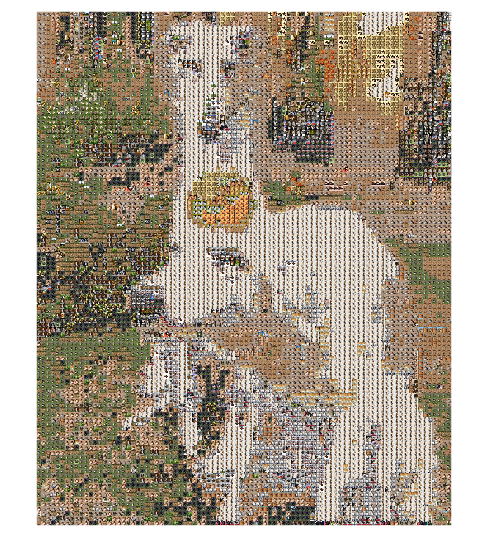

imshow(outputImage)

outputImage

outputImage = outputImage(:,:,1) =

    0.6529    0.6577    0.6639    0.6649    0.6597    0.6661    0.6692    0.6701    0.6674    0.6644    0.6630    0.6574    0.6677    0.6655    0.6634    0.6558    0.6584    0.6669    0.6659    0.6541    0.6514    0.6675    0.6897    0.7031    0.7121    0.7152    0.7186    0.7299    0.7292    0.7247    0.7266    0.7285    0.6529    0.6577    0.6639    0.6649    0.6597    0.6661    0.6692    0.6701    0.6674    0.6644    0.6630    0.6574    0.6677    0.6655    0.6634    0.6558    0.6584    0.6669    0.6659    0.6541    0.6514    0.6675    0.6897    0.7031    0.7121    0.7152    0.7186    0.7299    0.7292    0.7247    0.7266    0.7285    0.6529    0.6577    0.6639    0.6649    0.6597    0.6661    0.6692    0.6701    0.6674    0.6644    0.6630    0.6574    0.6677    0.6655    0.6634    0.6558    0.6584    0.6669    0.6659    0.6541    0.6514    0.6675    0.6897    0.7031    0.7121    0.7152    0.7186    0.7299    0.7292    0.7247    0.7266    0.7285    

Objective Comparisons

% S-CIELAB: Measures perceptual color differences with spatial filtering.
%scale output image to original size to comapre
outputImageResized = imresize(outputImage, size(targetImage(:,:,1)),"bicubic");
imwrite(outputImage, 'primColourDogNoDep.png');
%check same size
disp(size(outputImageResized));

   867   701     3



disp(size(targetImage));

   867   701     3




outputImageXYZ = rgb2xyz(outputImageResized);
targetImageXYZ = rgb2xyz(targetImage);


%calc PPI
screenHeight = 1440; %pixels
screenWidth = 2560; %pixels
hypPix = hypot(screenWidth, screenHeight);
hypInch = 27; %diagonal size (inches)
ppi = hypPix / hypInch;

d = 16; % ~40 cm 
sampPerDeg = ppi * d * tan(pi/180); % spd = ppi * avstånd till bild i inches * tan(pi/180)
CIED65samp = [95.05, 100, 108.9];

%full reference metric
scielabVal = scielab(sampPerDeg, outputImageXYZ, targetImageXYZ, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...



scielabAvg = mean(mean(scielabVal));
disp(['Average scielab value: ', num2str(scielabAvg)]);

Average scielab value: 1.5392


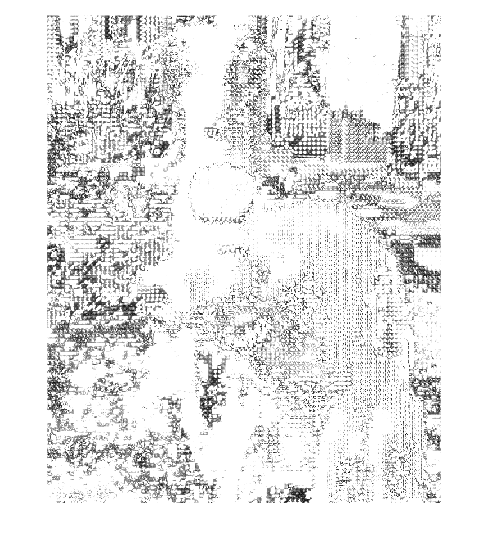

imshow(scielabVal)



% SSIM: Evaluates structural similarity based on luminance, contrast, and structure.
[dist2val, dist2map] = ssim(targetImage, outputImageResized);
disp(['SSIM Value: ', num2str(dist2val)]);

SSIM Value: 0.21329


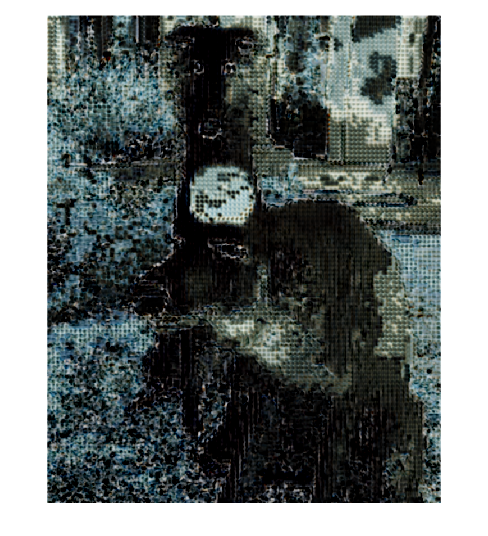

imshow(dist2map)

%imwrite(dist2map, 'dist2mapdark1nopre.png')

% PSNR: Quantifies the signal-to-noise ratio, useful for overall image fidelity.
psnrVal = psnr(targetImage, outputImageResized);
disp(['PSNR Value: ', num2str(psnrVal), ' dB']);

PSNR Value: 13.9718 dB
